# Photodiode - VEMD2020X01

Purpose: The photodiode serves to convert light into a small current. By measuring the light coming into the CubeSat, it can be useful to determine conditions. The current it outputs is passed further into the transimpedance amplifier where it makes the data that the photodiode is sensing into a processable signal.

Standard Modelling Technique: The photodiode was modelled using SimScape blocks and subsystems. By creating a subsystem for the photodiode (VEMD2020X01), inputs such as wavelength can be passed in and an output currentcan be determined. This model will help understand how wavelengths can affect the output current of the photodiode.

Datasheet:

https://www.vishay.com/docs/81962/vemd2000.pdf

## Model:

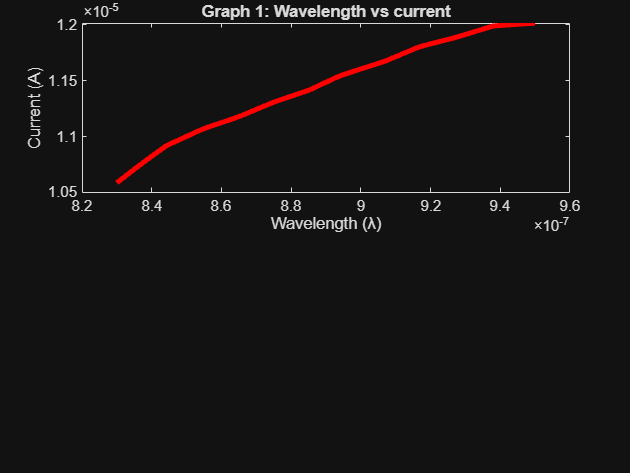

% Suppress all warnings
warning('off', 'all');

% Suppress specific algebraic loop warnings
warning('off', 'Simulink:Engine:AlgebraicLoop');

% Run the simulation and suppress command window output
evalc('sim_out = sim("C:\Users\timot\OneDrive\MATLAB\Components\Electrical\Models\Photodiode\photodiode_VEMD2020X01.slx")');

% Extract data for the first graph
current = sim_out.graph1.Data(:, 1);
wavelength = sim_out.graph1.Data(:, 2);

% Create a figure window
figure;

% First subplot
subplot(2, 1, 1);
plot(wavelength, current, 'r', 'LineWidth', 3); % Plot data
xlabel('Wavelength (λ)'); % Set x-axis label
ylabel('Current (A)'); % Set y-axis label
title('Graph 1: Wavelength vs current'); % Set title
set(gca, 'OuterPosition', [0, 0.5, 1, 0.5]); % Adjust outer position [left, bottom, width, height]